# Question 7

clear
clc
close all

addpath('./Data')
addpath('./Models')

load('ECP_values.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                     % Threshold angular velocity rad/s

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
sigma_meas = 0.0093*eye(3);     % Measurements covariance matrix

save_plots = true;

## State space representation


A = [0, 1, 0, 0, 0, 0; 
    -k_1/J_1, -b_1/J_1, k_1/J_1, 0, 0, 0; 
    0,0,0, 1,0,0; 
    k_1/J_2, 0, -(k_1 + k_2)/J_2, -b_2/J_2, k_2/J_2, 0; 
    0,0,0,0,0,1; 
    0,0, k_2/J_3, 0, -k_2/J_3, -b_3/J_3];

B = [0,0;
    1/J_1, 0; 
    0,0; 
    0,1/J_2; 
    zeros(2)];

C = [1, zeros(1,5); 0,0,1,zeros(1,3); zeros(1,4), 1, 0]; 
D = zeros(3,2); 
Ex = [0; -1/J_1; zeros(4,1)]; 
Ey = zeros(3,1);
Fx = [0,     0, 0, 0, 0;
    1/J_1,     0, 0, 0, 0;
    0,     0, 0, 0, 0;
    0, 1/J_2, 0, 0, 0;
    0,     0, 0, 0, 0;
    0,     0, 0, 0, 0];
Fy = [0,0,1,0,0;
       0,0,0,1,0;
       0,0,0,0,1];

% Discrete time

sys = ss(A, [B, Ex, Fx], C, [D, Ey, Fy]);
sys_d = c2d(sys,T_s, 'tustin');
F_d = sys_d.A;
G_d = sys_d.B(:,1:2);

% State-feedback LQR design
Q_c = diag([2 0 2 0 2.5 0.0024]);
R_c = diag([10 10]);
K_c = dlqr(F_d,G_d,Q_c,R_c);

% Scaling of reference
C_ref = pinv(C(3,:) * inv(eye(6) - F_d + G_d * K_c) * G_d * K_c);

% Kalman filter with friction estimation - DO NOT MODIFY
F_aug = [F_d G_d(:,1);zeros(1,6) 1];
G_aug = [G_d;0 0];
C_aug = [C zeros(3,1)];
% Kalman gain
L_aug = dlqe(F_aug,eye(7),C_aug,1e-3*eye(7),deg2rad(0.0056)*eye(3));
L_o = L_aug(1:6,:);
L_d = L_aug(7,:);

f_m_time = 10;
f_m = [0;0;0];

SIM_TIME = 50;
STEP_SIZE = 0.001;

out = sim('q7_TDO');

## Plots

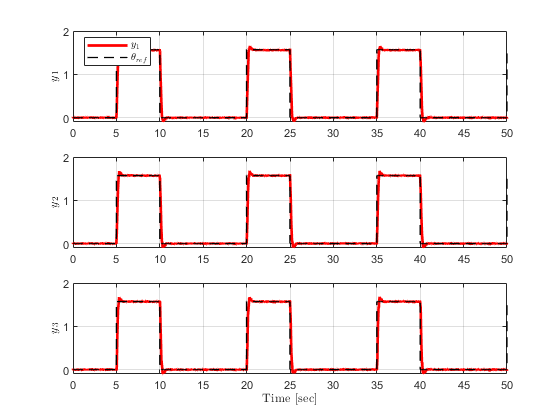

y = out.y.Data;

y1 = y(:,1);
y2 = y(:,2);
y3 = y(:,3);

t_d = out.y.Time;

theta_ref = out.theta_ref.Data;
theta_ref_time = out.theta_ref.Time;

figure(1)
subplot(3,1,1)
plot(t_d, y1, 'r', 'LineWidth', 2)
grid on
% xlabel('Time [sec]', "interpreter", "latex")
ylabel('$y_1$', "interpreter", "latex")

hold on
plot(theta_ref_time, theta_ref, 'k--', 'LineWidth', 1)
legend('$y_1$', '$\theta_{ref}$', "interpreter", "latex", 'location', 'NorthWest')

subplot(3,1,2)
plot(t_d, y2, 'r', 'LineWidth', 2)
grid on
% xlabel('Time [sec]', "interpreter", "latex")
ylabel('$y_2$', "interpreter", "latex")

hold on
plot(theta_ref_time, theta_ref, 'k--', 'LineWidth', 1)
% legend('$y_2$', '$\theta_{ref}$', "interpreter", "latex")

subplot(3,1,3)
plot(t_d, y3, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$y_3$', "interpreter", "latex")

hold on
plot(theta_ref_time, theta_ref, 'k--', 'LineWidth', 1)
% legend('$y_3$', '$\theta_{ref}$', "interpreter", "latex")

if save_plots
    saveas(gcf,'pics/q7_controller','epsc') 
end